# 创建一个石墨烯TB模型并拟合参数

## 创建石墨烯TB模型(step by step)

- 声明一个空的模型；初始化其轨道数

Graphene = HR(2)

Graphene =   HR - 属性:

      vectorL: [0 0 0]
        HnumL: [2×2 double]
        HcoeL: [2×2 sym]
        NRPTS: 1
      WAN_NUM: 2
     Line_000: 1
    Basis_num: []
           Rm: [3×3 double]
           Gk: [3×3 double]


- 修改POSCAR格式

*generated by phonopy*

*   1.0*

*     2.4604399204208875    0.0000000000000000    0.0000000000000000*

*    -1.2302199602104438    2.1308034755698513    0.0000000000000000*

*     0.0000000000000000    0.0000000000000000   10.0000000000000000*

*C*

*   2*

*Direct*

*  0.6666666666666666  0.3333333333333333  0.0000000000000000 *`C p z `

*  0.3333333333333334  0.6666666666666667  0.0000000000000000 *`C p z`

- 导入POSCAR

Graphene = Graphene <'POSCAR'

Graphene =   HR - 属性:

      vectorL: [0 0 0]
        HnumL: [2×2 double]
        HcoeL: [2×2 sym]
        NRPTS: 1
      WAN_NUM: 2
     Line_000: 1
    Basis_num: 2
           Rm: [3×3 double]
           Gk: [3×3 double]


% Graphene = Graphene.input_orb_struct('POSCAR')
Graphene.orbL

ans =   -0.333333333333333   0.333333333333333                   0
  -0.666666666666667   0.666666666666667                   0


- 进行 nn_sk 搜索

- 这里 search_range 取 【1 1 0】，Accuracy 取小数点3位，maxR值取 5 埃

search_range = [1 1 0];
Accuracy = 3;
r_max_search = 5;
Graphene = Graphene.nn_sk_smart(search_range,Accuracy ,r_max_search);

Seaching 2/2 th orb nn information ...
Giving 2/2 th orb nn_level ...


- 可以简要获取一下这一步的信息，看下Rnn排名

[Rnn,~,~,~] = Graphene.nn_information();

the   1 th Rnn vector:  1.4210 Angstrom
the   2 th Rnn vector:  2.4600 Angstrom
the   3 th Rnn vector:  2.8410 Angstrom
the   4 th Rnn vector:  3.7580 Angstrom
the   5 th Rnn vector:  4.2620 Angstrom


- 这里我们取最近邻hopping

level_cut = 1;
Graphene = Graphene.H_TB_gen_SK(level_cut)

setting (   1/   2) th orbital ... 
setting (   2/   2) th orbital ... 


Graphene =   HR - 属性:

      vectorL: [5×3 int32]
        HnumL: [2×2×5 double]
        HcoeL: [2×2×5 sym]
        NRPTS: 5
      WAN_NUM: 2
     Line_000: 1
    Basis_num: 2
           Rm: [3×3 double]
           Gk: [3×3 double]


- 查看一下体系的未知量（symbolic）

Graphene.symvar_list

$$ans = {\mathrm{VppP}}_{1}$$

## 利用MATLAB(2020)控件调整参数

- 导入 KPOINTS信息 高对称点 高对称路径

 Graphene = Graphene<'KPOINTS';

- 创建滑块


VppP_1 = 2.4;
Fermi = 0;

- 给TB中的符号化变量赋值

Graphene_n = Graphene.Subsall();

- 生成 hr.dat

Graphene_n.Gen_hr()

Wrinting (1/5)  NRPT
Wrinting (2/5)  NRPT
Wrinting (3/5)  NRPT
Wrinting (4/5)  NRPT
Wrinting (5/5)  NRPT


ans =      3


- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

- 画出能带

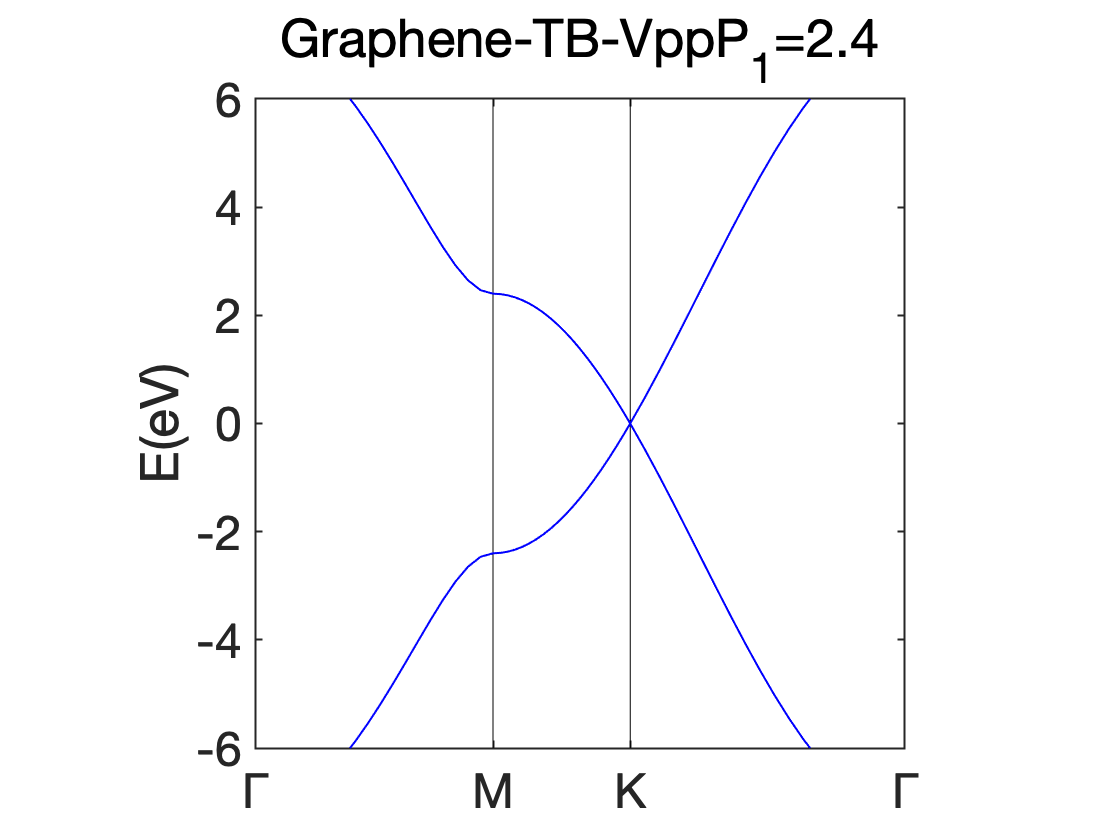

bandplot(EIGENCAR,[-6,6],...
    'title',"Graphene-TB-VppP_1="+string(VppP_1),'Color','b');

## 利用MATLAB(2020)控件调整参数 - DFT

- 导入DFT数据

EIGENCAR_DFT = EIGENVAL_read; 

- 引入此近邻

level_cut = 2;
Graphene = Graphene.H_TB_gen_SK(level_cut); 

setting (   1/   2) th orbital ... 
-1 0 0 2 1 
0 1 0 2 1 
setting (   2/   2) th orbital ... 
0 -1 0 1 2 
1 0 0 1 2 


Graphene.symvar_list

$$ans = \left(\begin{array}{cc} {\mathrm{VppP}}_{1} & {\mathrm{VppP}}_{2} \end{array}\right)$$

- 创建滑块

VppP_1 = 2.7;
VppP_2 = 0.6;
Fermi = 1.6;

- 给TB中的符号化变量赋值

Graphene = Graphene<'KPOINTS';
Graphene_n = Graphene.Subsall();

- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

- 使用bandcompare画出能带

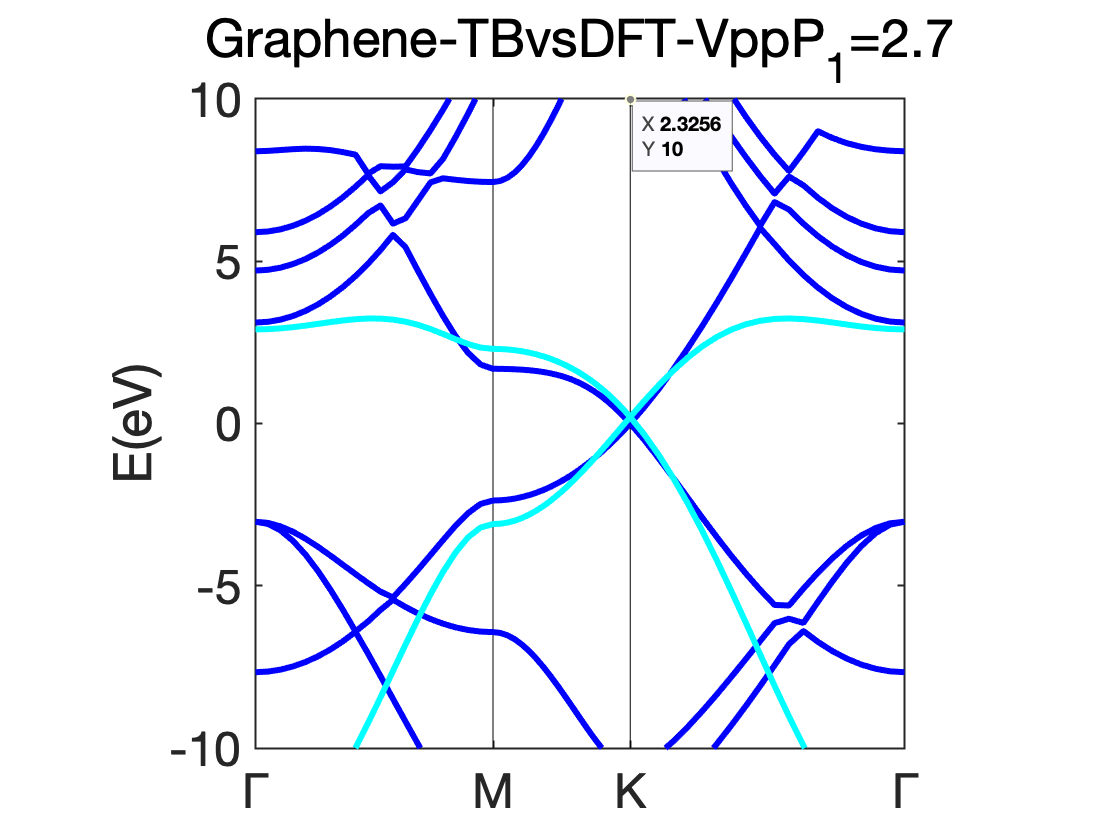

bandplot({EIGENCAR_DFT,EIGENCAR} ,[-10,10],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## TBSK单参数拟合

设定拟合范围：

options_extra.NBAND_range_DFT = [4:5];
options_extra.NBAND_range = [1:2];
options_extra.klist_range = [30:50];

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

Graphene_single = subs(Graphene,Graphene.symvar_list(2),0);
Loss_func_GrapheneTB = @(para) vasplib.loss_func(para, ...
    'FITobj','Graphene_single',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)                     

Loss_func_GrapheneTB = 包含以下值的 function_handle :
    @(para)vasplib.loss_func(para,'FITobj','Graphene_single','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


 
 Func-count     x          f(x)         Procedure
    1        1.76393      1.24419        initial
    2        2.23607     0.778041        golden
    3        2.52786     0.511701        golden
    4         2.7082       0.4195        golden
    5        2.91864     0.499609        parabolic
    6        2.73003     0.421649        parabolic
    7         2.6862     0.422678        parabolic
    8        2.71023     0.419388        parabolic
    9        2.71278     0.419281        parabolic
   10        2.71937     0.420025        golden
   11        2.71872     0.419934        parabolic
   12        2.71505     0.419431        golden
   13        2.71244     0.419288        parabolic
   14        2.71366      0.41927        parabolic
   15        2.71419     0.419327        golden
   16        2.71363     0.419266        parabolic
   17         2.7133     0.419271        golden
   18        2.71349     0.419267        parabolic
   19        2.71356     0.419266        parabolic
  

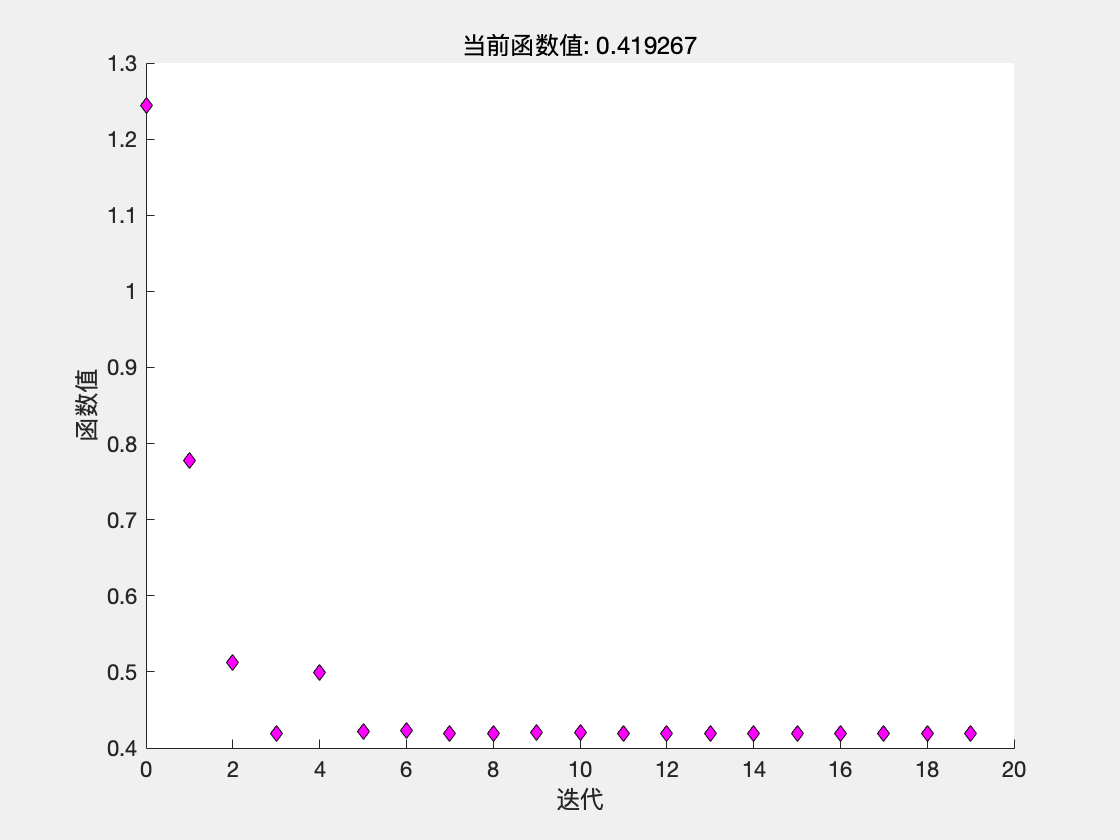

options = optimset('PlotFcns',@optimplotfval,'Display','iter');
VppP_1 = fminbnd(Loss_func_GrapheneTB,1,3,options);

Graphene_single_n = Graphene_single.subs(Graphene_single.symvar_list(1),VppP_1);
EIGENCAR = Graphene_single_n.EIGENCAR_gen();

- 使用bandcompare画出能带

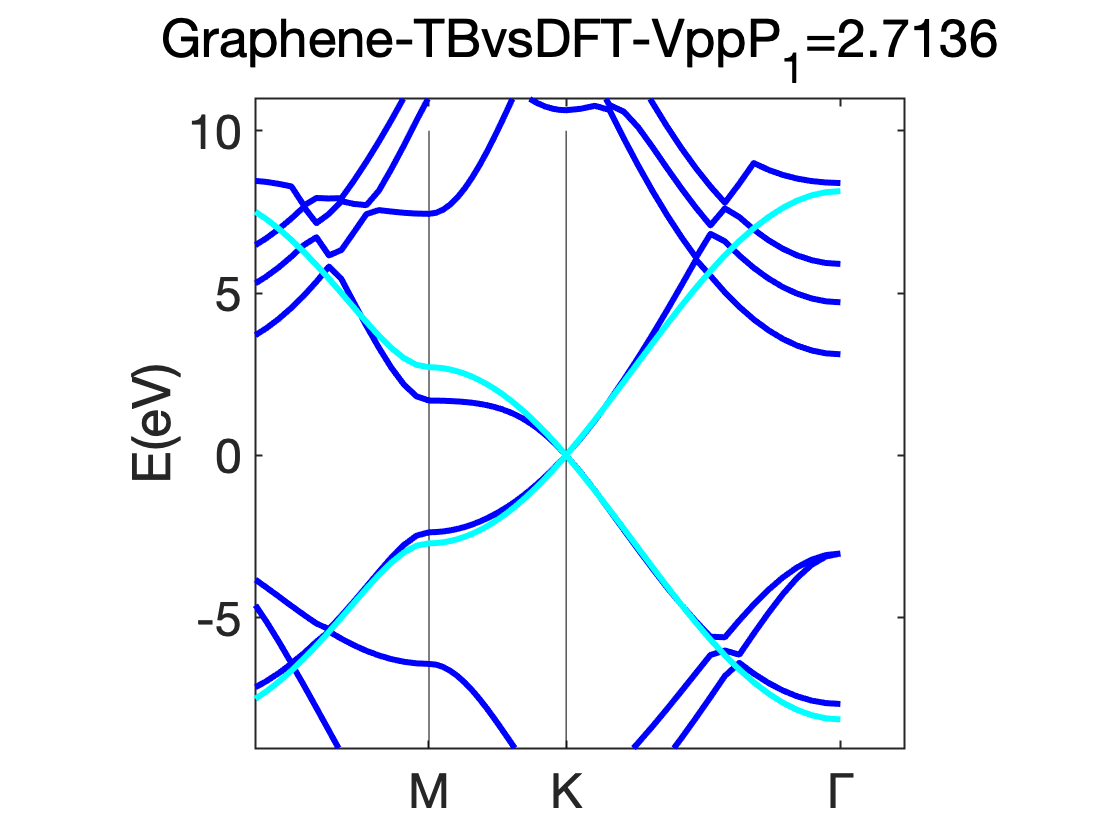

bandplot({EIGENCAR_DFT,EIGENCAR} ,[-10,10],'title',"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## 利用NM办法多参数拟合DFT

clear;
EIGENCAR_DFT = EIGENVAL_read; 

generated by phonopy

   1.0

     2.4604399204208875    0.0000000000000000    0.0000000000000000

    -1.2302199602104438    2.1308034755698513    0.0000000000000000

     0.0000000000000000    0.0000000000000000   10.0000000000000000

C

   8

Direct

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C s I

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p x

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p y

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C s I

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p x

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p y

  0.6666666666666666  0.3333333333333333  0.0000000000000000 C p z 

  0.3333333333333334  0.6666666666666667  0.0000000000000000 C p z

### 创建模型 Script模式

Graphene = HR.from_POSCAR_SE('POSCAR_All',...
'mode','list',...
'search_range' ,[2 2 0],...
'r_max',2,...
'level_cut',2);

Generating 8/8 th orb nn information ...
Giving nn_level for 96/96 th hopping  ...
Setting 96/96 th orbital ...


$$\left(\begin{array}{cccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

### 利用MATLAB(2020)控件调整参数 - DFT

E__6_0 = -7;
E__6_1 = 0;
VppP_1 = 2.7;
VppS_1 = -4;
VspS_1 = -4;
VssS_1 = 4;
Fermi  = 0;

Graphene_n = Graphene.Subsall();

- 生成能带

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

- 画出能带

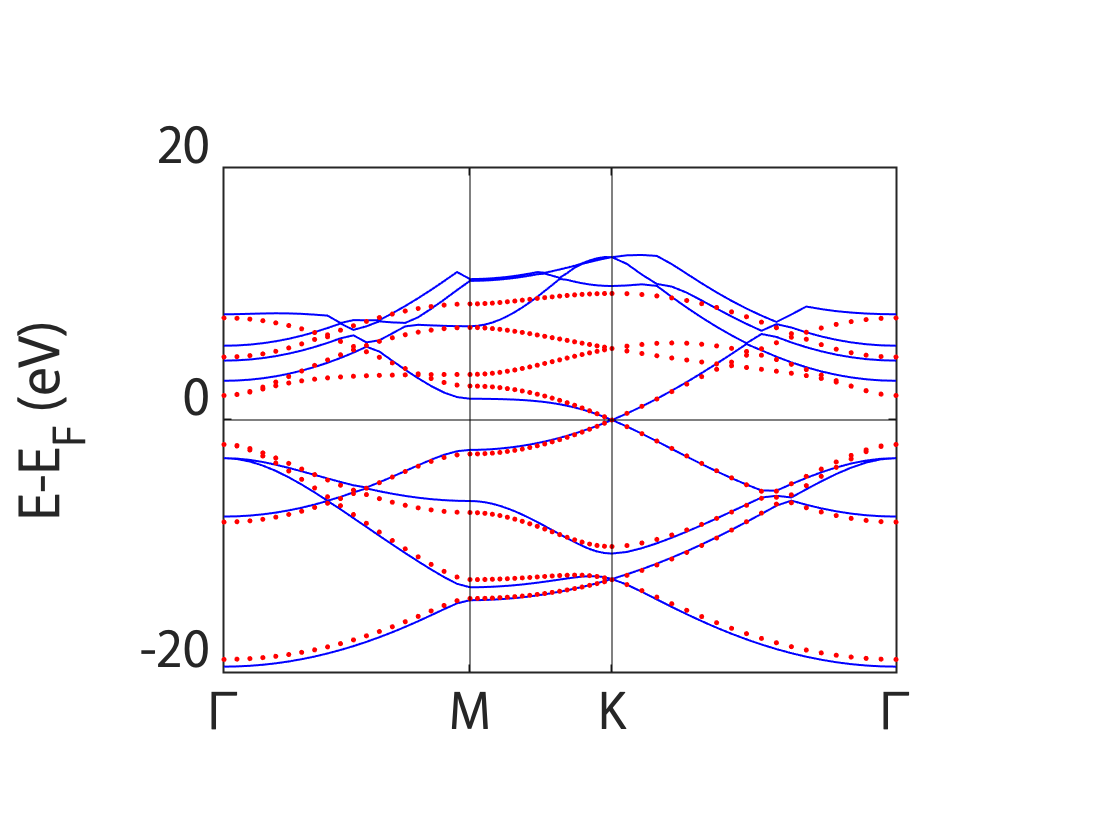

bandcompare(EIGENCAR_DFT,EIGENCAR ,[-20,20],"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

### NM

#### 拟合参数设置

设定拟合范围：

options_extra.NBAND_range_DFT = [1:4];
options_extra.NBAND_range = [1:4];
options_extra.klist_range = ':';

默认大小和斜率等权

options_extra.weight_list = [1,1];

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

- FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

Graphene_single = subs(Graphene,Graphene.symvar_list(2),0);
Loss_func_TB = @(para) vasplib.loss_func(para, ...
    'FITobj','Graphene',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','pure_comparison' ...
)          

Loss_func_TB = 包含以下值的 function_handle :
    @(para)vasplib.loss_func(para,'FITobj','Graphene','DFTBAND','EIGENCAR_DFT','extra','options_extra','algorithm','pure_comparison')


#### 初值给定

Graphene = Graphene.subs([sym('E__6_1') sym('VppP_1')],[0,2.71353]);
Graphene.symvar_list

$$ans = \left(\begin{array}{cccc} E_{0}^{6} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} \end{array}\right)$$

x0 = [-7,-4,-4,4];

#### 进行拟合

 
 Iteration   Func-count     min f(x)         Procedure
     0            1         0.638837         
     1            5          0.58167         initial simplex
     2            7         0.562154         reflect
     3            9         0.562154         contract inside
     4           11         0.562154         contract outside
     5           12         0.562154         reflect
     6           14         0.562154         contract inside
     7           16         0.559635         reflect
     8           17         0.559635         reflect
     9           19         0.551949         reflect
    10           21         0.551949         contract inside
    11           23         0.551471         reflect
    12           24         0.551471         reflect
    13           26         0.540994         expand
    14           28         0.540994         contract inside
    15           29         0.540994         reflect
    16           31         0.540994         contract 

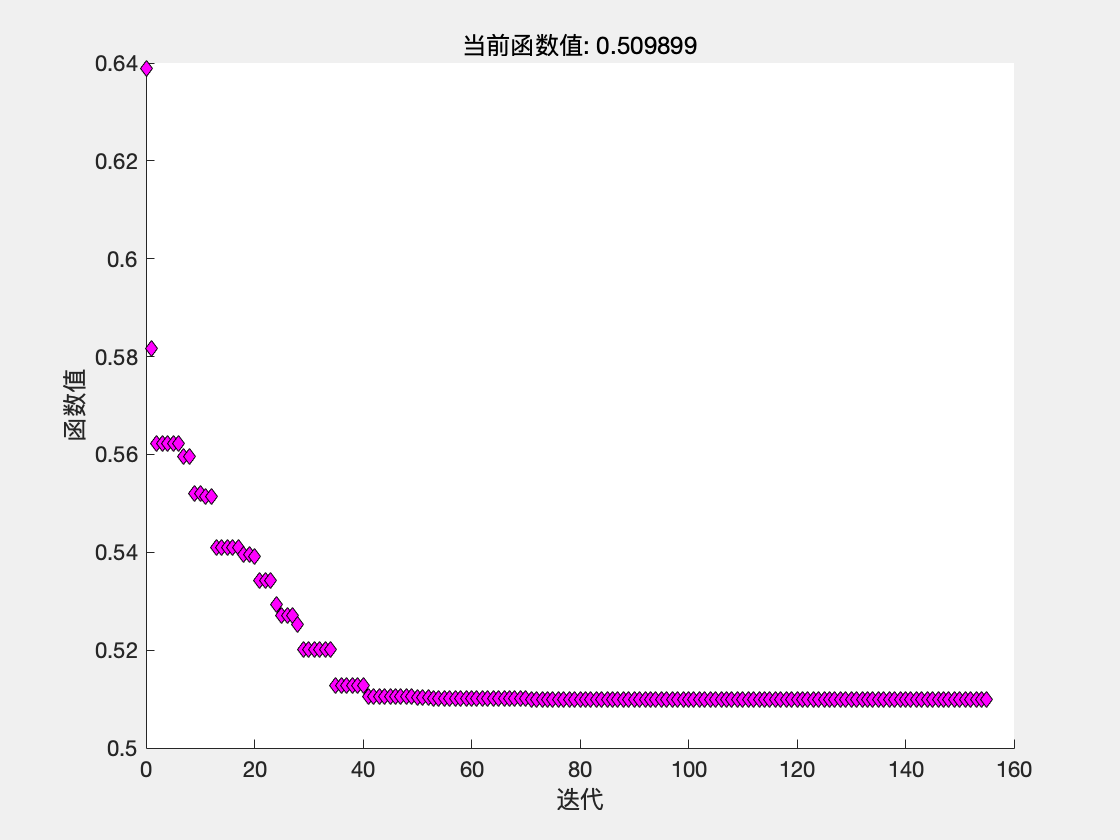

 
优化已终止:
 当前的 x 满足使用 1.000000e-04 的 OPTIONS.TolX 的终止条件，
F(X) 满足使用 1.000000e-04 的 OPTIONS.TolFun 的收敛条件



options = optimset('PlotFcns',@optimplotfval,'Display','iter');
x = fminsearch(Loss_func_TB,x0,options);

#### 拟合结果

[Graphene_n,EQL] = Graphene.subs(x);
EQL

$$EQL = \left(\begin{array}{cccc} E_{0}^{6}=-4.91067 & {\mathrm{VppS}}_{1}=-4.30822 & {\mathrm{VspS}}_{1}=-4.79034 & {\mathrm{VssS}}_{1}=4.88644 \end{array}\right)$$

EIGENCAR = Graphene_n.EIGENCAR_gen()-Fermi;

- 画出能带

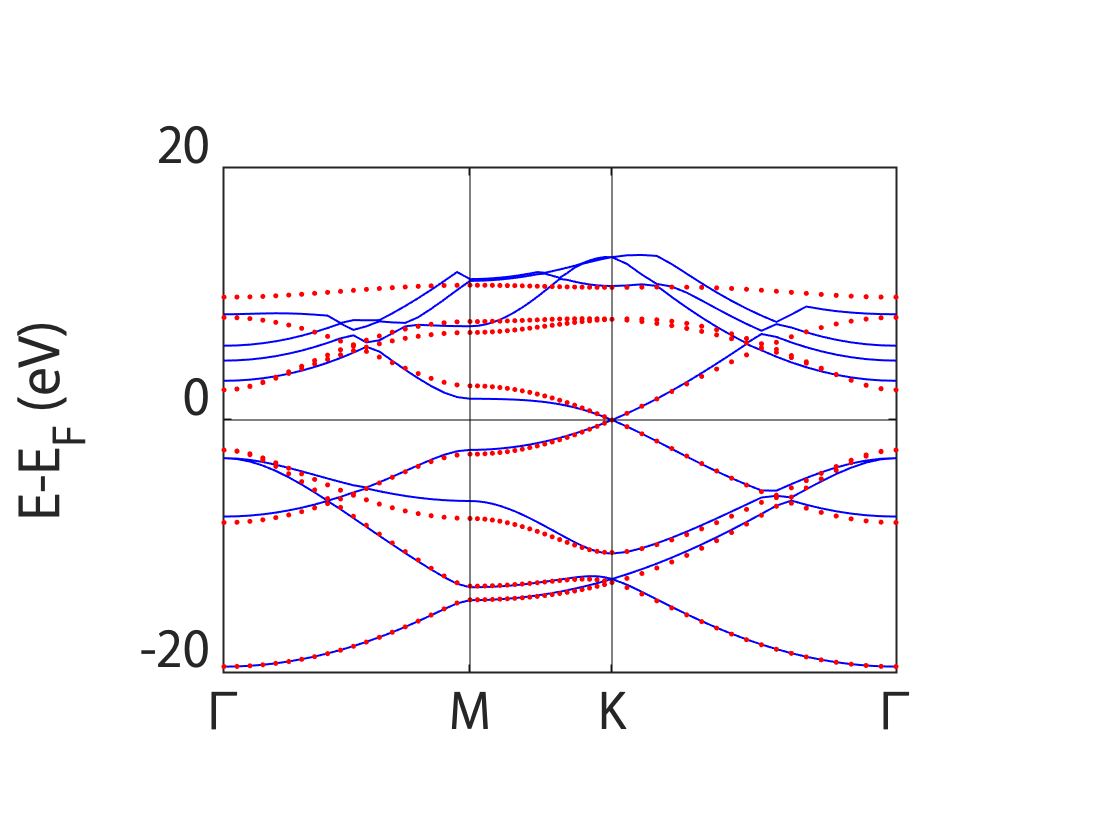

bandcompare(EIGENCAR_DFT,EIGENCAR ,[-20,20],"Graphene-TBvsDFT-VppP_1="+string(VppP_1));

## Bayes 拟合

我们尝试在什么都不知道的情况下拟合能带

开启delta rule

Graphene = HR.from_POSCAR_SE('POSCAR_All',...
'mode','list',...
'search_range' ,[2 2 0],...
'r_max',4,...
'level_cut',2,...
'deltarule',1);

Generating 8/8 th orb nn information ...
Giving nn_level for 576/576 th hopping  ...
Setting 288/288 th orbital ...
the   1 th Rnn vector:  1.4210 Angstrom
the   2 th Rnn vector:  2.4600 Angstrom
the   3 th Rnn vector:  2.8410 Angstrom
the   4 th Rnn vector:  3.7580 Angstrom


$$\left(\begin{array}{ccccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} & \delta \end{array}\right)$$

一般地 我们可以参考 DFT2wannier的结果 (轨道顺序一致)

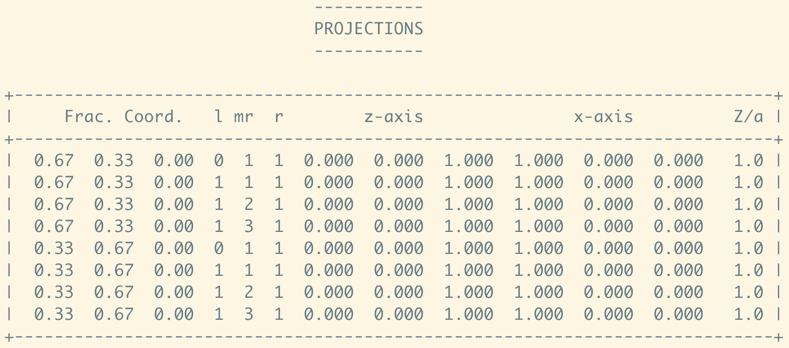

EIGENCAR_DFT = EIGENVAL_read; 
GrapheneWan = HR.from_wannier90()

GrapheneWan =   HR - 属性:

        vectorL: [147×3 double]
          HnumL: [8×8×147 double]
          HcoeL: [8×8×147 sym]
          NRPTS: 147
        WAN_NUM: 8
       Line_000: 74
      Basis_num: []
             Rm: [3×3 double]
             Gk: [3×3 double]
    symvar_list: [1×0 sym]


[VarInit,EQL] =GetInit(Graphene,GrapheneWan,[1,0,0])

VarInit = 包含以下字段的 struct :
    E__6_0: [0×1 sym]
    E__6_1: [0×1 sym]
    VppP_1: [0×1 sym]
    VppS_1: [0×1 sym]
    VspS_1: [0×1 sym]
    VssS_1: [0×1 sym]
     delta: [0×1 sym]


$$EQL = \begin{array}{l} \left(\begin{array}{c} {\mathrm{VppP}}_{1}=-1.88071+0.011532\,\mathrm{i}\\ {\mathrm{VssS}}_{1}=0.024936+0.110278\,\mathrm{i}\\ {\mathrm{VppP}}_{1}\,{\mathrm{e}}^{-\frac{0.731175}{\delta }}=-1.27739+0.013419\,\mathrm{i}\\ {\mathrm{VssS}}_{1}\,{\mathrm{e}}^{-\frac{0.731175}{\delta }}=-2.13801+0.018338\,\mathrm{i}\\ -0.500089\,{\mathrm{VspS}}_{1}=-7.0755-0.061722\,\mathrm{i}\\ 0.500089\,{\mathrm{VspS}}_{1}=0.913644-0.100861\,\mathrm{i}\\ -0.144389\,{\mathrm{VppP}}_{1}+0.144389\,{\mathrm{VppS}}_{1}=1.15099-0.009681\,\mathrm{i}\\ -0.288727\,{\mathrm{VspS}}_{1}=0.768319-0.156482\,\mathrm{i}\\ 0.288727\,{\mathrm{VspS}}_{1}=0.009919-0.051425\,\mathrm{i}\\ 0.916637\,{\mathrm{VppP}}_{1}+0.0833631\,{\mathrm{VppS}}_{1}=-0.557761+0.032491\,\mathrm{i}\\ 0.749911\,{\mathrm{VppP}}_{1}+0.250089\,{\mathrm{VppS}}_{1}=3.42637-0.022149\,\mathrm{i}\\ -\sigma_{1}=-0.545579+0.08189\,\mathrm{i}\\ \sigma_{1}=1.78773-0.013438\,\mathrm{i}\\ -4.44089e-16\,{\mathrm{e}}^{-\frac{0.731175}{\delta }}\,\left(8.05448e+11\,{\mathrm{VppP}}_{1}-2.25261e+15\,{\mathrm{VppS}}_{1}\right)=1.65693+0.066534\,\mathrm{i} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1.00018\,{\mathrm{VspS}}_{1}\,{\mathrm{e}}^{-\frac{0.731175}{\delta }} \end{array}$$

通过比照


$$E_0^6 =7.41207$$



$$E_1^6 =5.35906$$



$${\textrm{VppP}}_1 =-1.89184$$



$${\textrm{VssS}}_1 =0.346063$$



$${\textrm{VspS}}_1 =4.19456$$



$${\textrm{VppS}}_1 \;\;=\;?$$



$$\delta =?$$


### 构建Bayes 寻参模型

#### 拟合参数设置

设定拟合范围：

options_extra = vasplib.FitOptionHelper(EIGENCAR_DFT,'dirac',...
'Noccu',4,'NBAND_range_DFT',1:4,'highK',[1,20,40,60],'GapThreshold',0.3);    

默认大小和斜率等权

键值对：

-  ‘EIGENCAR_DFT’ 为你的DFT 能带变量名

-  FITobj 为你的拟合对象变量名

-  ‘extra’ 为你的设定的能量范围

-  'algorithm' 为你选择的比较方法 默认为同时比较大小和斜率

extra_parm = 0;
Loss_func_TB = @(para,extra_parm) vasplib.loss_func(para,extra_parm, ...
    'FITobj','Graphene',...
    'DFTBAND','EIGENCAR_DFT',...
    'extra','options_extra',...
    'algorithm','dirac' ...
)       
   

#### Bayse 模型设置

Varlist = Graphene.symvar_list

$$Varlist = \left(\begin{array}{ccccccc} E_{0}^{6} & E_{1}^{6} & {\mathrm{VppP}}_{1} & {\mathrm{VppS}}_{1} & {\mathrm{VspS}}_{1} & {\mathrm{VssS}}_{1} & \delta \end{array}\right)$$

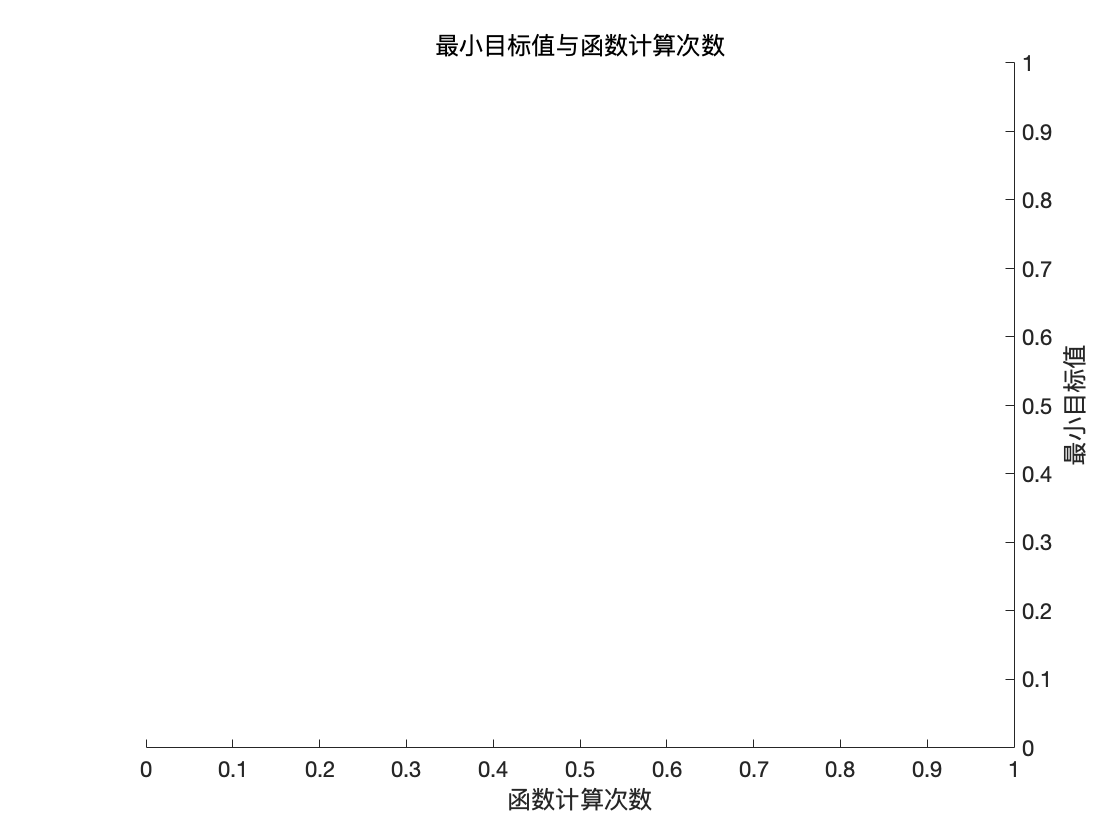

调用 "vasplib.EIGENCAR_Value" 时，未对输出参数 "ValueTotal" (可能还包括其他参数)赋值。

出错 vasplib.loss_func (第 2126 行)
            Value = vasplib.EIGENCAR_Value(EIGENCAR_DFT,EIGENCAR_vasplib,extra_parm,...

出错 TBSK_fit_Graphene (第 99 行)
Loss_func_TB = @(para,extra_parm) vasplib.loss_func(para,extra_parm, ...

出错 

VarGuess = [7.41207,5.353906,-1.8901,0.3456,4.19456,0,0];
Varlock  = VarGuess;
VarFix = sym([]);
VarWidth = [10,10,5,7,7,7,1];
fixCriterion = 1e-2;
BayesCycle = 5;
for i = 1 : BayesCycle
    extra_parm = 1-i/BayesCycle;
    Ratio = 0.7 - 0.4*(i /BayesCycle);
    Max_num = 40 + 20*(i /BayesCycle);
    Loss_func = @(parm) Loss_func_TB(parm,extra_parm);
    %
    VarBayes = vasplib.VarBayes(Varlist,VarGuess,VarWidth,VarFix);
    results = bayesopt(Loss_func,VarBayes,'Verbose',1,...
        'AcquisitionFunctionName','expected-improvement-plus',...
        'ExplorationRatio',Ratio,...
        'MaxObjectiveEvaluations',Max_num ...
        );
    %
    VarGuess_nex_time = table2array(results.XAtMinEstimatedObjective);
    Varlock = VarGuess;
    VarWidth = VarWidth/2^i;
    fixVarible = abs(VarGuess_nex_time - VarGuess) < fixCriterion;
    VarFix = Varlist(fixVarible);
    VarGuess = VarGuess_nex_time;
end

[Graphene_n,EQL] = Graphene.subs(VarGuess);
EQL

$$EQL = \left(\begin{array}{ccccccc} E_{0}^{6}=-7.80546 & E_{1}^{6}=-2.91872 & {\mathrm{VppP}}_{1}=0.395664 & {\mathrm{VppS}}_{1}=-5.10558 & {\mathrm{VspS}}_{1}=-5.01913 & {\mathrm{VssS}}_{1}=4.61071 & \delta =0.353068 \end{array}\right)$$

EIGENCAR = Graphene_n.EIGENCAR_gen();

- 画出能带

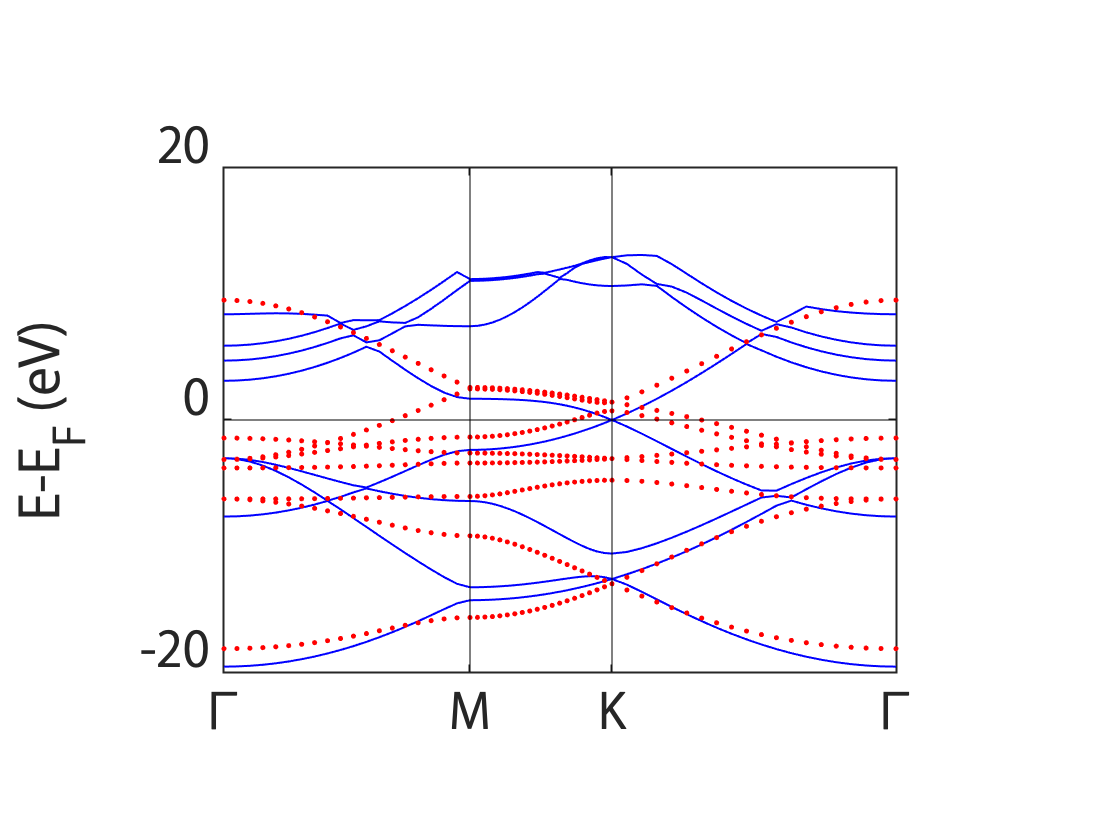

bandcompare(EIGENCAR_DFT,EIGENCAR ,[-20,20]);